% ========================================================================
% Bacteria-Phage Stochastic Dynamics Simulation
% ========================================================================
% This script models the stochastic interactions between susceptible bacteria,
% infected bacteria, and bacteriophages using the Gillespie Stochastic 
% Simulation Algorithm (SSA).
% Demonstrates two scenarios: constant vs. oscillating carrying capacity.
% ========================================================================

%% ==================== Scenario 1: Constant Carrying Capacity (A = 0) ====================
clear; clc;

    %% ==================== Parameter Settings ====================
    % Biological parameters
    r = 1.0;          % Bacterial growth rate (time^-1)
    K0 = 1000;        % Baseline environmental carrying capacity (individuals)
    A = 0;            % Carrying capacity fluctuation amplitude (individuals)
    
    % [Modification 1] Changed angular frequency w to frequency f, where f = w/(2*pi). 
    % Original w=1, so f=1/(2*pi)
    f = 0.5;          % Frequency (Hz)
    w = 2*pi*f;       % Angular frequency w is still used for internal calculations
    
    ef_a = 0.015;
    a = ef_a / K0;    % Infection rate (individual^-1 * time^-1)
    alpha = 2;        % Lysis rate (time^-1)
    Omega = 50;       % Number of phages released per lysis event
    delta = 0.04;     % Phage decay rate (time^-1)
    
    % Initial conditions (must be integers!)
    B0 = 0.2*K0;      % Initial susceptible bacteria count
    I0 = 0.0*K0;      % Initial infected bacteria count
    P0 = 0.1*K0;      % Initial phage count
    
    % Simulation parameters
    t_end = 500;      % Simulation end time
    n_runs = 50;      % [Modification 2] Number of independent simulations n (adjust as needed)
    
    %% ==================== Run n Independent Simulations ====================
    fprintf('Starting %d Gillespie stochastic simulations...\n', n_runs);

Starting 50 Gillespie stochastic simulations...


    fprintf('Parameters: r=%.2f, K0=%d, A=%d, f=%.4f, a=%.5f, alpha=%.2f, Omega=%d, delta=%.2f\n\n', ...
            r, K0, A, f, a, alpha, Omega, delta);

Parameters: r=1.00, K0=1000, A=0, f=0.5000, a=0.00001, alpha=2.00, Omega=50, delta=0.04



    
    figure('Position', [100, 100, 900, 600]);
    hold on;
    survival_count = 0; % Survival counter
    
    for i = 1:n_runs
        fprintf('Running simulation %d/%d...\n', i, n_runs);
        
        % Call SSA function (passing f)
        [t, B, I, P, K_history, stop_reason] = gillespie_ssa(t_end, B0, I0, P0, r, K0, A, f, a, alpha, Omega, delta);
        
        % [Modification 2] Plot the B time series from all n runs on a single figure
        plot(t, B, 'LineWidth', 1.2);
        
        % [Modification 3] Check if B survives (B > 0 at the end of simulation)
        if B(end) > 0
            survival_count = survival_count + 1;
        end
    end

Running simulation 1/50...
Running simulation 2/50...
Running simulation 3/50...
Running simulation 4/50...
Running simulation 5/50...
Running simulation 6/50...
Running simulation 7/50...
Running simulation 8/50...
Running simulation 9/50...
Running simulation 10/50...
Running simulation 11/50...
Running simulation 12/50...
Running simulation 13/50...
Running simulation 14/50...
Running simulation 15/50...
Running simulation 16/50...
Running simulation 17/50...
Running simulation 18/50...
Running simulation 19/50...
Running simulation 20/50...
Running simulation 21/50...
Running simulation 22/50...
Running simulation 23/50...
Running simulation 24/50...
Running simulation 25/50...
Running simulation 26/50...
Running simulation 27/50...
Running simulation 28/50...
Running simulation 29/50...
Running simulation 30/50...
Running simulation 31/50...
Running simulation 32/50...
Running simulation 33/50...
Running simulation 34/50...
Running simulation 35/50...
Running simulation 36/50...
R

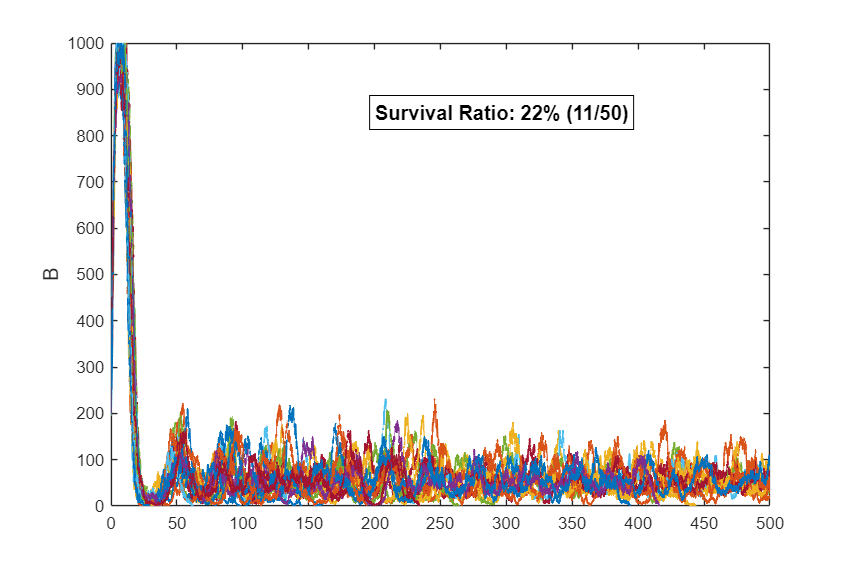

    hold off;
    
    %% ==================== Result Visualization & Statistics ====================
    % [Modification 3] Calculate survival ratio and annotate on the plot
    survival_ratio = survival_count / n_runs;
    xlim([0,500]);
    ylim([0,1000]);
    %xlabel('Time', 'FontSize', 12);
    ylabel('B', 'FontSize', 12);
    %title(sprintf('%d Independent Simulations - Susceptible Bacteria B Dynamics', n_runs), 'FontSize', 14);
    grid off;
    box on;
    % Add survival ratio text box to the figure
    text(t_end*0.4, K0*0.85, sprintf('Survival Ratio: %.0f%% (%d/%d)', survival_ratio*100, survival_count, n_runs), ...
     'FontSize', 12, 'FontWeight', 'bold', 'BackgroundColor', 'w', 'EdgeColor', 'k');

         
    fprintf('\n=== Simulation Complete ===\n');


=== Simulation Complete ===


    fprintf('Bacteria B survival ratio: %.2f%% (%d/%d)\n', survival_ratio*100, survival_count, n_runs);

Bacteria B survival ratio: 22.00% (11/50)




%% ==================== Scenario 2: Oscillating Carrying Capacity (A = 800) ====================
clear; clc;

    %% ==================== Parameter Settings ====================
    % Biological parameters
    r = 1.0;          % Bacterial growth rate (time^-1)
    K0 = 1000;        % Baseline environmental carrying capacity (individuals)
    A = 800;          % Carrying capacity fluctuation amplitude (individuals)
    
    % [Modification 1] Changed angular frequency w to frequency f, where f = w/(2*pi). 
    % Original w=1, so f=1/(2*pi)
    f = 0.5;          % Frequency (Hz)
    w = 2*pi*f;       % Angular frequency w is still used for internal calculations
    
    ef_a = 0.015;
    a = ef_a / K0;    % Infection rate (individual^-1 * time^-1)
    alpha = 2;        % Lysis rate (time^-1)
    Omega = 50;       % Number of phages released per lysis event
    delta = 0.04;     % Phage decay rate (time^-1)
    
    % Initial conditions (must be integers!)
    B0 = 0.2*K0;      % Initial susceptible bacteria count
    I0 = 0.0*K0;      % Initial infected bacteria count
    P0 = 0.1*K0;      % Initial phage count
    
    % Simulation parameters
    t_end = 500;      % Simulation end time
    n_runs = 50;      % [Modification 2] Number of independent simulations n (adjust as needed)
    
    %% ==================== Run n Independent Simulations ====================
    fprintf('Starting %d Gillespie stochastic simulations...\n', n_runs);

Starting 50 Gillespie stochastic simulations...


    fprintf('Parameters: r=%.2f, K0=%d, A=%d, f=%.4f, a=%.5f, alpha=%.2f, Omega=%d, delta=%.2f\n\n', ...
            r, K0, A, f, a, alpha, Omega, delta);

Parameters: r=1.00, K0=1000, A=800, f=0.5000, a=0.00001, alpha=2.00, Omega=50, delta=0.04



    
    figure('Position', [100, 100, 900, 600]);
    hold on;
    survival_count = 0; % Survival counter
    
    for i = 1:n_runs
        fprintf('Running simulation %d/%d...\n', i, n_runs);
        
        % Call SSA function (passing f)
        [t, B, I, P, K_history, stop_reason] = gillespie_ssa(t_end, B0, I0, P0, r, K0, A, f, a, alpha, Omega, delta);
        
        % [Modification 2] Plot the B time series from all n runs on a single figure
        plot(t, B, 'LineWidth', 1.2);
        
        % [Modification 3] Check if B survives (B > 0 at the end of simulation)
        if B(end) > 0
            survival_count = survival_count + 1;
        end
    end

Running simulation 1/50...
Running simulation 2/50...
Running simulation 3/50...
Running simulation 4/50...
Running simulation 5/50...
Running simulation 6/50...
Running simulation 7/50...
Running simulation 8/50...
Running simulation 9/50...
Running simulation 10/50...
Running simulation 11/50...
Running simulation 12/50...
Running simulation 13/50...
Running simulation 14/50...
Running simulation 15/50...
Running simulation 16/50...
Running simulation 17/50...
Running simulation 18/50...
Running simulation 19/50...
Running simulation 20/50...
Running simulation 21/50...
Running simulation 22/50...
Running simulation 23/50...
Running simulation 24/50...
Running simulation 25/50...
Running simulation 26/50...
Running simulation 27/50...
Running simulation 28/50...
Running simulation 29/50...
Running simulation 30/50...
Running simulation 31/50...
Running simulation 32/50...
Running simulation 33/50...
Running simulation 34/50...
Running simulation 35/50...
Running simulation 36/50...
R

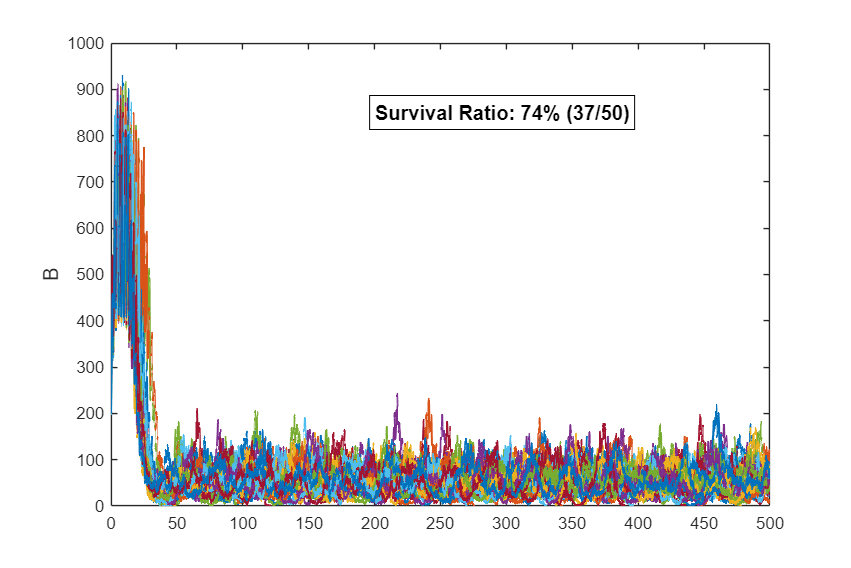

    hold off;
    
    %% ==================== Result Visualization & Statistics ====================
    % [Modification 3] Calculate survival ratio and annotate on the plot
    survival_ratio = survival_count / n_runs;
    xlim([0,500]);
    ylim([0,1000]);
    %xlabel('Time', 'FontSize', 12);
    ylabel('B', 'FontSize', 12);
    %title(sprintf('%d Independent Simulations - Susceptible Bacteria B Dynamics', n_runs), 'FontSize', 14);
    grid off;
    box on;
    % Add survival ratio text box to the figure
    text(t_end*0.4, K0*0.85, sprintf('Survival Ratio: %.0f%% (%d/%d)', survival_ratio*100, survival_count, n_runs), ...
     'FontSize', 12, 'FontWeight', 'bold', 'BackgroundColor', 'w', 'EdgeColor', 'k');

         
    fprintf('\n=== Simulation Complete ===\n');


=== Simulation Complete ===


    fprintf('Bacteria B survival ratio: %.2f%% (%d/%d)\n', survival_ratio*100, survival_count, n_runs);

Bacteria B survival ratio: 74.00% (37/50)




%% ==================== Gillespie SSA Core Function ====================


function [t, B, I, P, K_history, stop_reason] = gillespie_ssa(t_end, B0, I0, P0, r, K0, A, f, a, alpha, Omega, delta)
    w = 2*pi*f; % Convert frequency to angular frequency for internal calculations
    
    % Initialization
    t = 0;
    B = B0;
    I = I0;
    P = P0;
    stop_reason = 'Unknown';
    
    % Calculate initial K value (K=K0 at t=0)
    K = A * sin(w * t) + K0;
    K = max(K, 1);  % Ensure K remains positive
    
    % Preallocate memory
    max_reactions_fixed = 10000000;
    max_reactions_alloc = 10000000;
    
    t_history = zeros(max_reactions_alloc, 1);
    B_history = zeros(max_reactions_alloc, 1);
    I_history = zeros(max_reactions_alloc, 1);
    P_history = zeros(max_reactions_alloc, 1);
    K_history = zeros(max_reactions_alloc, 1);
    
    % Initial record
    idx = 1;
    t_history(idx) = t;
    B_history(idx) = B;
    I_history(idx) = I;
    P_history(idx) = P;
    K_history(idx) = K;
    
    reaction_count = 0;
    
    % ==================== Main Loop ====================
    while t < t_end && reaction_count < max_reactions_fixed
        % Check termination condition for B=0
        if B == 0
            stop_reason = 'B=0 (Bacterial extinction)';
            break;
        end
        
        % Step 1: Calculate propensity functions
        N = B + I;
        
        a1 = r * B;
        a2 = (r / K) * N * B;
        a3 = a * B * P;
        a4 = alpha * I;
        a5 = delta * P;
        
        a_vec = [a1, a2, a3, a4, a5];
        a0 = sum(a_vec);
        
        if a0 == 0
            stop_reason = 'a0=0 (No reactions possible)';
            break;
        end
        
        % Step 2: Generate random numbers
        r1 = rand();
        r2 = rand();
        
        % Step 3: Calculate tau and mu
        tau = (1.0 / a0) * log(1.0 / r1);
        
        % Select reaction type
        cum_sum = 0;
        mu = 0;
        for i = 1:5
            cum_sum = cum_sum + a_vec(i);
            if cum_sum > r2 * a0
                mu = i;
                break;
            end
        end
        
        % Step 4: Update state
        t = t + tau;
        reaction_count = reaction_count + 1;
        idx = idx + 1;
        
        % Update K value based on new time t
        K = A * sin(w * t) + K0;
        K = max(K, 1);
        
        % Update population counts based on reaction type
        switch mu
            case 1, B = B + 1;
            case 2, B = max(0, B - 1);
            case 3, B = max(0, B - 1); P = max(0, P - 1); I = I + 1;
            case 4, I = max(0, I - 1); P = P + Omega;
            case 5, P = max(0, P - 1);
        end
        
        % Step 5: Record data
        if idx > max_reactions_alloc
            max_reactions_alloc = max_reactions_alloc * 2;
            t_history(idx:max_reactions_alloc) = 0;
            B_history(idx:max_reactions_alloc) = 0;
            I_history(idx:max_reactions_alloc) = 0;
            P_history(idx:max_reactions_alloc) = 0;
            K_history(idx:max_reactions_alloc) = 0;
        end
        
        t_history(idx) = t;
        B_history(idx) = B;
        I_history(idx) = I;
        P_history(idx) = P;
        K_history(idx) = K;
    end
    
    % Set termination reason
    if isempty(stop_reason) || strcmp(stop_reason, 'Unknown')
        if t >= t_end
            stop_reason = 't >= t_end (Reached end time)';
        elseif reaction_count >= max_reactions_fixed
            stop_reason = 'reaction_count >= max (Reached max reaction count)';
        end
    end
    
    % Truncate output
    t = t_history(1:idx);
    B = B_history(1:idx);
    I = I_history(1:idx);
    P = P_history(1:idx);
    K_history = K_history(1:idx);
end